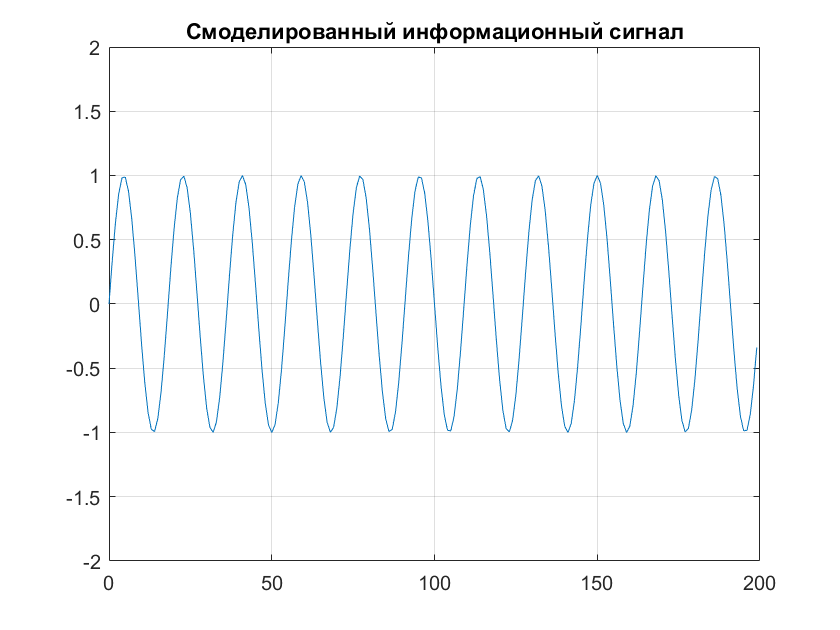

clc;
close all;
clear all;

signal = sin(2*pi*0.055*(0:1000-1)');
signalSource = dsp.SignalSource(signal,'SamplesPerFrame',100,...
    'SignalEndAction','Cyclic repetition');

plot(0:199,signal(1:200));
grid; axis([0 200 -2 2]);
title('Смоделированный информационный сигнал');

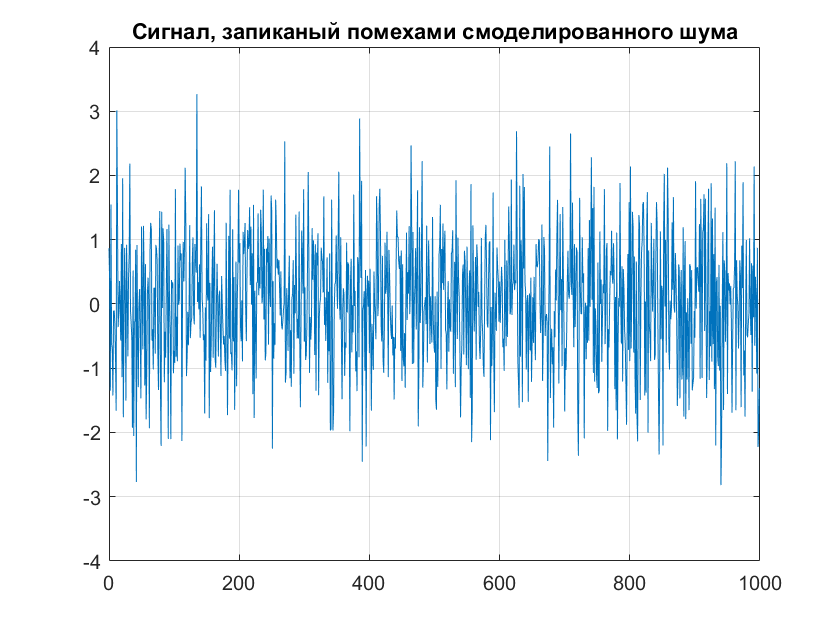


nvar  = 1.0;                  % Noise variance
noise = randn(1000,1)*nvar;   % White noise
noiseSource = dsp.SignalSource(noise,'SamplesPerFrame',100,...
    'SignalEndAction','Cyclic repetition');

plot(0:999,noise);
title('Сигнал, запиканый помехами смоделированного шума');
grid; axis([0 1000 -4 4]);

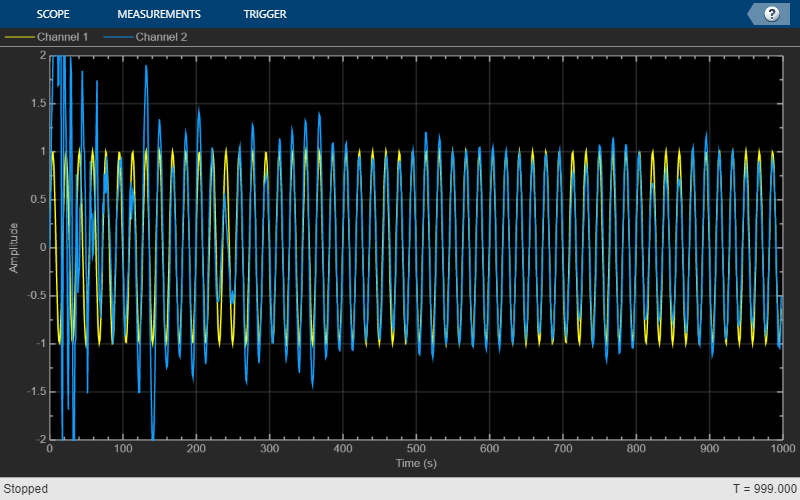



lp = dsp.FIRFilter('Numerator',fir1(31,0.5));% Low pass FIR filter

M      = 32;                 % Filter order
delta  = 0.1;                % Initial input covariance estimate
P0     = (1/delta)*eye(M,M); % Initial setting for the P matrix
rlsfilt = dsp.RLSFilter(M,'InitialInverseCovariance',P0);

scope = timescope('TimeSpanSource','property','TimeSpan',1000, ...
                  'YLimits',[-2,2]);
for k = 1:10
    n = noiseSource(); % Noise
    s = signalSource();
    d = lp(n) + s;
    [y,e]  = rlsfilt(n,d);
    scope([s,e]);
end
release(scope);

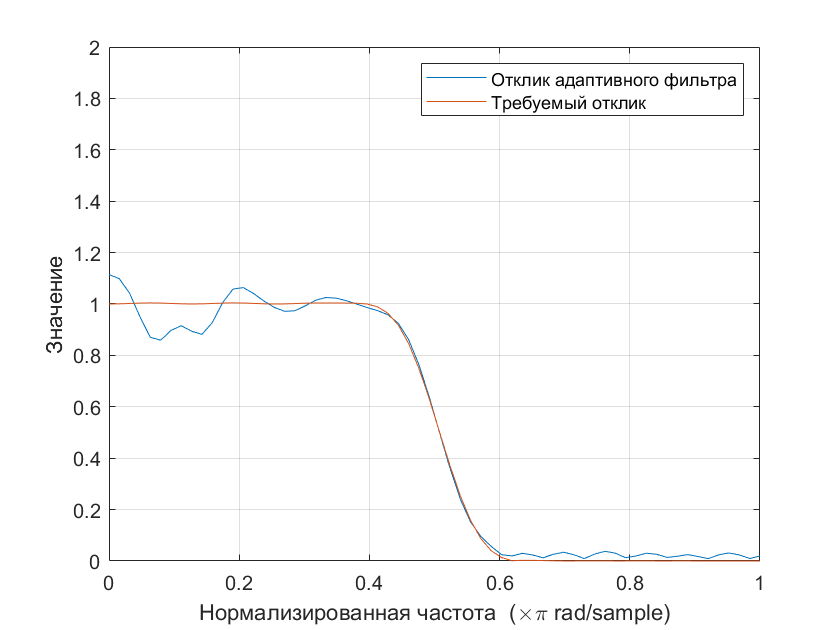


H  = abs(freqz(rlsfilt.Coefficients,1,64));
H1 = abs(freqz(lp.Numerator,1,64));

wf = linspace(0,1,64);

plot(wf,H,wf,H1);
xlabel('Нормализированная частота  (\times\pi rad/sample)');
ylabel('Значение');
legend('Отклик адаптивного фильтра','Требуемый отклик');
grid;
axis([0 1 0 2]);